% RGB = imread('pillsetc.png');
% imshow(RGB)
% 
% I = rgb2gray(RGB);
% bw = imbinarize(I);
% imshow(bw)
% 
% bw = bwareaopen(bw,30);
% imshow(bw)
% 
% se = strel('disk',2);
% bw = imclose(bw,se);
% imshow(bw)
% 
% bw = imfill(bw,'holes');
% imshow(bw)
% 
% [B,L] = bwboundaries(bw,'noholes');
% 
% imshow(label2rgb(L,@jet,[.5 .5 .5]))
% hold on
% for k = 1:length(B)
%   boundary = B{k};
%   plot(boundary(:,2),boundary(:,1),'w','LineWidth',2)
% end
    


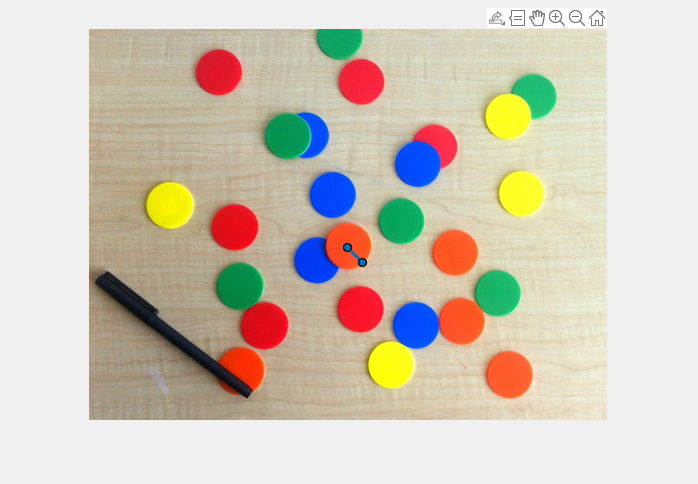

rgb = imread('coloredChips.png');
imshow(rgb)
d = drawline;

pos = d.Position;
diffPos = diff(pos);
diameter = hypot(diffPos(1),diffPos(2))

diameter = 21.2132

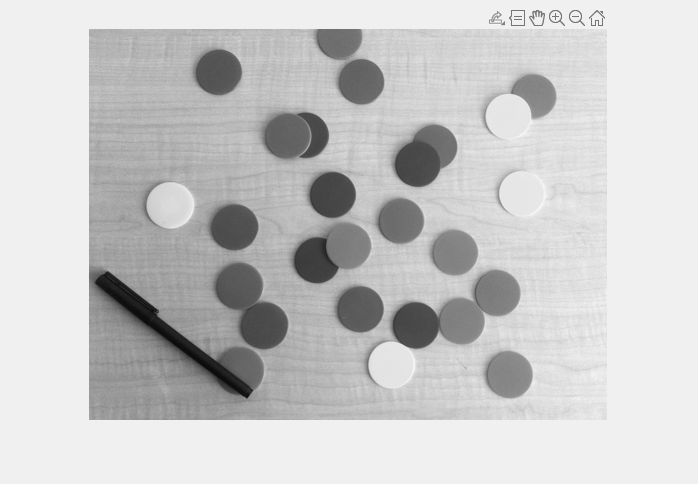

gray_image = rgb2gray(rgb);
imshow(gray_image)

[centers,radii] = imfindcircles(rgb,[20 25],'ObjectPolarity','dark')


centers =

     []


radii =

     []



[centers,radii] = imfindcircles(rgb,[20 25],'ObjectPolarity','dark', ...
    'Sensitivity',0.9)

centers =   146.1895  198.5824
  328.8132  135.5883
  130.3134   43.8039
  175.2698  297.0583
  312.2831  192.3709
  327.1316  297.0077
  243.9893  166.4538
  271.5873  280.8920


radii =    23.1604
   22.5710
   22.9576
   23.7356
   22.9551
   22.9995
   22.9055
   23.0298


imshow(rgb)
h = viscircles(centers,radii);

[centers,radii] = imfindcircles(rgb,[20 25],'ObjectPolarity','dark', ...
    'Sensitivity',0.92);

length(centers)

ans = 16

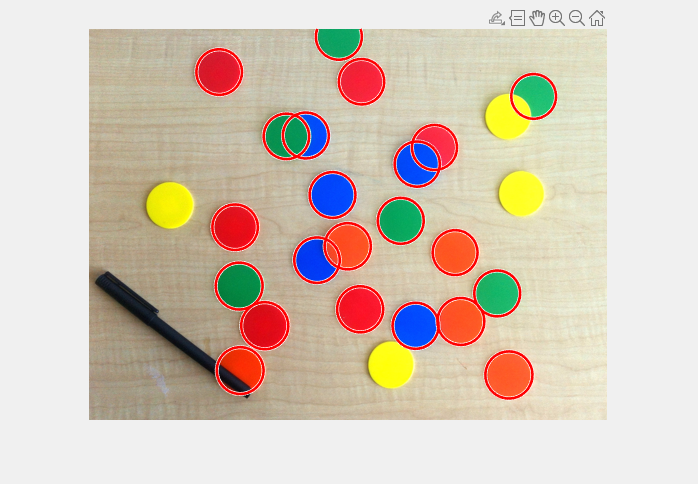


delete(h)  % Delete previously drawn circles
h = viscircles(centers,radii);

[centers,radii] = imfindcircles(rgb,[20 25],'ObjectPolarity','dark', ...
          'Sensitivity',0.92,'Method','twostage');

delete(h)
h = viscircles(centers,radii);

[centers,radii] = imfindcircles(rgb,[20 25],'ObjectPolarity','dark', ...
          'Sensitivity',0.95);

delete(h)
viscircles(centers,radii);


imshow(gray_image)

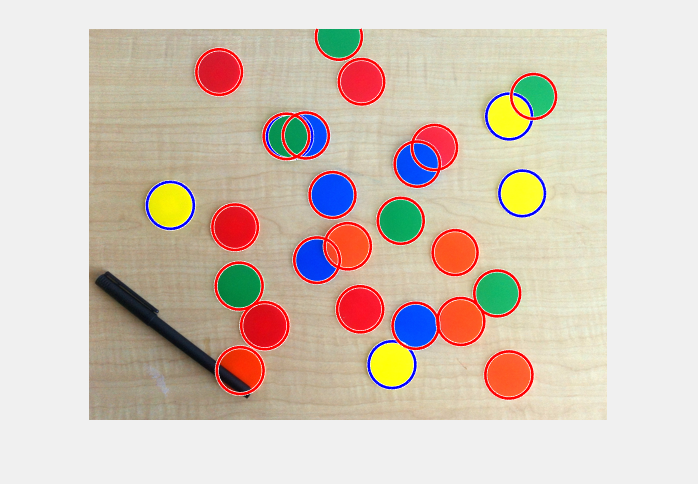



[centersBright,radiiBright] = imfindcircles(rgb,[20 25], ...
    'ObjectPolarity','bright','Sensitivity',0.92);


imshow(rgb)

hBright = viscircles(centersBright, radiiBright,'Color','b');

[centersBright,radiiBright,metricBright] = imfindcircles(rgb,[20 25], ...
    'ObjectPolarity','bright','Sensitivity',0.92,'EdgeThreshold',0.1);

delete(hBright)
hBright = viscircles(centersBright, radiiBright,'Color','b');

h = viscircles(centers,radii);